# **Projeto Eletromag**

**1. Modelando a antena **

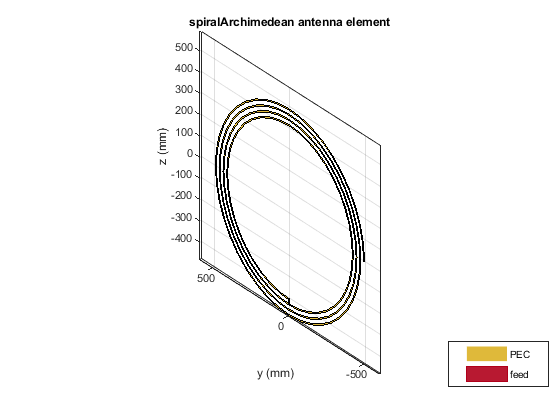

antE = spiralArchimedean('NumArms',1,'Turns',4, 'InnerRadius',40e-2, 'OuterRadius',50e-2,"Tilt",90,"TiltAxis","Y");
show(antE)

**2. Calculando a impedância de sua antena**

freq = linspace(7e7,8.5e7,200)

freq = 	1.0e+07 *

    7.0000    7.0075    7.0151    7.0226    7.0302    7.0377    7.0452    7.0528    7.0603    7.0678    7.0754    7.0829    7.0905    7.0980    7.1055    7.1131    7.1206    7.1281    7.1357    7.1432    7.1508    7.1583    7.1658    7.1734    7.1809    7.1884    7.1960    7.2035    7.2111    7.2186    7.2261    7.2337    7.2412    7.2487    7.2563    7.2638    7.2714    7.2789    7.2864    7.2940    7.3015    7.3090    7.3166    7.3241    7.3317    7.3392    7.3467    7.3543    7.3618    7.3693


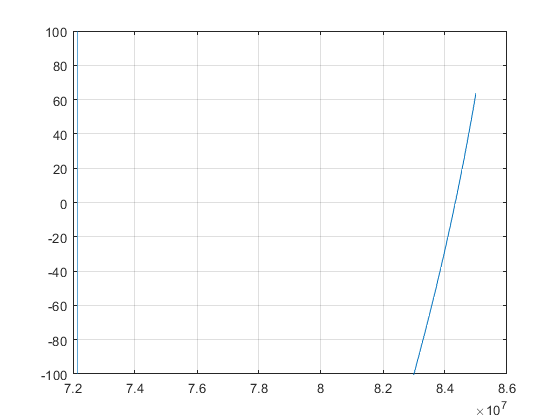

impedancia = impedance(antE,freq);
img = imag(impedancia);
plot(freq,img)
ylim([-100, 100])
grid

% frequencia de ressonancia = 8.43e7 para img zero e wc = 7.215e7

**3. Antena receptora**

antR = spiralArchimedean('NumArms',1,'Turns',4, 'InnerRadius',40e-2, 'OuterRadius',50e-2,'Tilt',90,"TiltAxis","Y");
show(antR)

Array de antenas

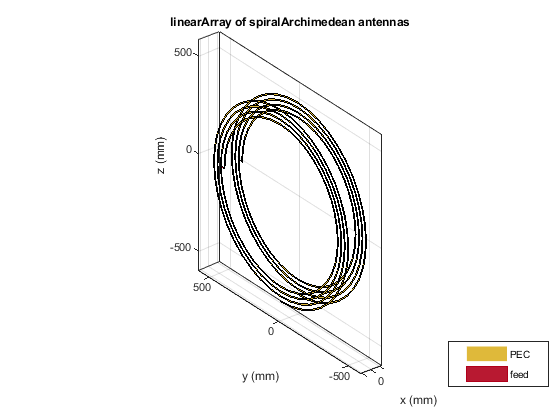

la = linearArray('Element',[antE,antR],'Tilt',90);
la.ElementSpacing = 10e-2;
show(la)

**4. Simulando o acoplamento**

ganhos = sparameters(la, freq);

**5. Visualizando os ganhos **

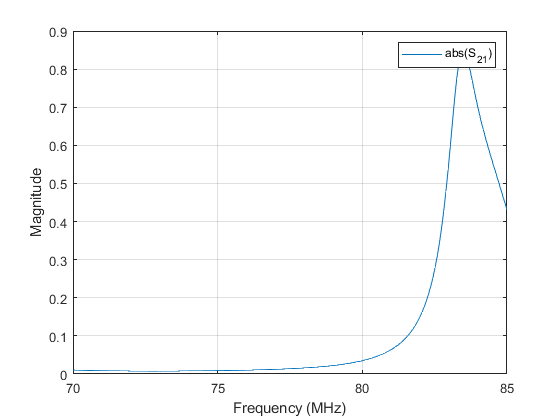

rfplot(ganhos,2,1,'abs')

ganhos_db = abs(rfparam(ganhos,2,1))

ganhos_db =     0.0105
    0.0103
    0.0101
    0.0099
    0.0098
    0.0096
    0.0094
    0.0093
    0.0092
    0.0091


**6. Visualização 3D** 

distancias = linspace(5e-2, 50e-2,8)
len_dist = length(distancias)
len_freq = length(freq)

distancias =     0.0500    0.1143    0.1786    0.2429    0.3071    0.3714    0.4357    0.5000


M_ganhos = []

len_dist = 8

len_freq = 200

for i = 1:length(distancias)


M_ganhos =

     []



lista_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176


lista_ganhos =     0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.0067    0.0067


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

lista_ganhos =     0.0054    0.0053    0.0052    0.0051    0.0050    0.0049    0.0049    0.0048    0.0047    0.0047    0.0046    0.0046    0.0045    0.0045    0.0044    0.0044    0.0044    0.0043    0.0043    0.0043    0.0043    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0042    0.0043    0.0043    0.0043    0.0043    0.0044    0.0044    0.0044    0.0044    0.0045    0.0045


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

lista_ganhos =     0.0047    0.0047    0.0046    0.0045    0.0044    0.0044    0.0043    0.0042    0.0042    0.0041    0.0041    0.0040    0.0040    0.0039    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0038    0.0038    0.0038    0.0038    0.0038    0.0039    0.0039    0.0039    0.0039    0.0040


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

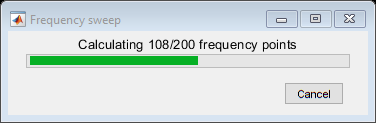

lista_ganhos =     0.0046    0.0046    0.0045    0.0044    0.0043    0.0043    0.0042    0.0041    0.0041    0.0040    0.0040    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0037    0.0037    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0037    0.0037    0.0037    0.0037    0.0037    0.0038    0.0038    0.0038    0.0038


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

lista_ganhos =     0.0047    0.0046    0.0045    0.0044    0.0043    0.0043    0.0042    0.0042    0.0041    0.0041    0.0040    0.0040    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0037    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0037    0.0037    0.0037    0.0037    0.0037    0.0038    0.0038    0.0038


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

lista_ganhos =     0.0047    0.0046    0.0045    0.0044    0.0044    0.0043    0.0042    0.0042    0.0041    0.0041    0.0040    0.0040    0.0039    0.0039    0.0039    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0037    0.0037    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0037    0.0037    0.0037    0.0037    0.0037    0.0037    0.0038    0.0038


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

lista_ganhos =     0.0047    0.0046    0.0045    0.0045    0.0044    0.0043    0.0043    0.0042    0.0041    0.0041    0.0040    0.0040    0.0040    0.0039    0.0039    0.0038    0.0038    0.0038    0.0038    0.0037    0.0037    0.0037    0.0037    0.0037    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0036    0.0037    0.0037    0.0037    0.0037    0.0037    0.0038    0.0038


M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

    la.ElementSpacing = distancias(i);
    ganhos_3d = sparameters(la, freq);
    lista_ganhos = rot90(abs(rfparam(ganhos_3d,2,1)))
    M_ganhos = [M_ganhos;lista_ganhos]
end

M_ganhos

M_ganhos =     0.0238    0.0233    0.0229    0.0226    0.0222    0.0219    0.0216    0.0213    0.0210    0.0208    0.0205    0.0203    0.0201    0.0199    0.0197    0.0195    0.0193    0.0192    0.0190    0.0189    0.0187    0.0186    0.0185    0.0184    0.0183    0.0182    0.0181    0.0180    0.0180    0.0179    0.0178    0.0178    0.0177    0.0177    0.0177    0.0176    0.0176    0.0176    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0175    0.0176    0.0176    0.0176    0.0176
    0.0087    0.0085    0.0084    0.0082    0.0081    0.0079    0.0078    0.0077    0.0076    0.0075    0.0074    0.0073    0.0072    0.0071    0.0071    0.0070    0.0069    0.0069    0.0068    0.0068    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0066    0.0066    0.0066    0.0066    0.00

Plotando o grafico 3d

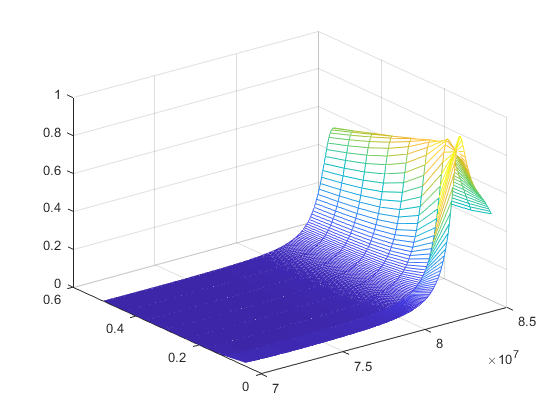

mesh(freq, distancias, M_ganhos)